# THA 4

## Caleb's Version


clear
% clc
%set jacobian and transform criteria, and bring in robot for animation
L=[.100 .265 .360 .360 .175];
omega=[
    0,0,1;%1
    0,1,0;%2
    0,0,-1;%3
    0,1,0;%4
    0,0,1;%5
    0,-1,0;%6
    0,0,1;%7
    0,-1,0;%8
    ];
q=[
    [-L(1),-L(2)-L(3)-L(4)-L(5),0];%1
    [0,-L(3)-L(4)-L(5),0];%2
    [0,-L(3)-L(4)-L(5),0];%3
    [0,-L(4)-L(5),0];%4
    [0,-L(4)-L(5),0];%5
    [0,-L(4)-L(5),0];%6
    [0,-L(5),0];%7
    [0,0,0];%8
    ];
home=[
    1 0 0 0;
    0 1 0 -L(2)-L(3)-L(4)-L(5);
    0 0 1 0;
    0 0 0 1
    ];
robot = importrobot('csda10f.urdf');
robot.DataFormat='row';

theta_expected=[0 ones(1,7)*pi/2]

theta_expected =          0    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708


%% using home as starting config (joint angles)
T_sb=home

T_sb =     1.0000         0         0         0
         0    1.0000         0   -1.1600
         0         0    1.0000         0
         0         0         0    1.0000


%% arbitrary goal point
T_sd=getTransform(robot,[theta_expected pi/2 pi/2 zeros(1,6)],"arm_left_link_7_t")

T_sd =    -0.0000    1.0000    0.0000    0.5524
   -0.0024    0.0000   -1.0000    0.3826
   -1.0000   -0.0000    0.0024    0.8393
         0         0         0    1.0000




%initial guess, setting error criteria
theta=pi/4*ones(1,8) %zeros returns singularity

theta =     0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854



epsilon_w=.01;
epsilon_v=.01;

% set initial omega_b and v_b
omega_b=eye(3,3)*2;
v_b=eye(3,3)*2;

% loops=50 %%set iterations for test
F = struct('cdata',[],'colormap',[]);


% for i=1:loops  %this is only until I figure out why it doesnt converge
i=0

i = 0

i = 1

V =     0.8594
   -0.7964
   -0.1117
    0.0909
    0.4860
    0.9846


theta =    -0.5019   -1.2966   -1.6934    0.9198   -1.2326    0.8989    0.6825    0.6014


i = 2

V =     1.4285
    1.8037
   -1.4470
   -0.2532
    0.3131
    0.2391


theta =    -1.8606    0.3860   -1.3886    0.3542   -3.1376   -1.6459    2.3611   -1.9635


i = 3

V =     0.2800
   -1.3698
    1.0739
    0.5792
    0.5393
   -0.1047


theta =     0.7469    2.1845   -4.1251   35.9808   -2.0989  -34.3910    2.3344   -8.6966


i = 4

V =     2.1187
    1.3089
    1.7238
   -0.3185
    0.3567
    0.5401


theta =     1.1892    1.0013   -4.3398   34.3366   -3.8040  -35.9148    1.5946   -8.2145


i = 5

V =    -0.0033
   -0.5931
    1.3667
    0.1222
    0.6476
   -0.0366


theta =     0.3949    0.7744   -5.8714   32.0506   -3.8897  -35.9910    0.7468   -9.1210


i = 6

V =     1.8873
   -0.6884
    0.3522
    0.4096
    0.4483
    0.8294


theta =    -1.8878    0.0016   -8.9544   32.1912   -7.3098  -40.1942    0.7943  -13.5885


i = 7

V =    -0.9039
    0.3164
    0.1130
    0.0835
    0.3793
   -0.1425


theta =    -1.1271   -0.2897   -7.3334   32.6308   -5.9897  -40.4780    1.0932  -14.9538


i = 8

V =    -0.7431
    0.7470
   -0.0985
    0.3502
    0.2084
    0.2596


theta =    -0.4338    0.4287   -6.2634   33.3029   -6.6924  -41.2396    1.1798  -16.3065


i = 9

V =     0.7188
    0.9516
    0.7431
    0.4036
    0.0548
    0.4337


theta =    -0.0629    0.7585   -5.5889   33.6739   -4.8720  -41.3483    3.5846  -16.5917


i = 10

V =     1.5293
    0.7141
    0.4392
    0.2356
    0.0244
   -0.1128


theta =    -0.6137    0.7293   -6.2437   34.1825   -5.5509  -41.3959    3.6163  -17.3603


i = 11

V =     1.9830
   -0.9089
   -0.6374
    0.1402
   -0.3338
   -0.1107


theta =    -0.7862    0.3815   -6.3034   33.9092   -4.7409  -43.9282    4.9746  -17.0259


i = 12

V =     0.0124
   -1.5045
    2.7304
    0.6959
    0.6021
    0.3744


theta =    -1.8472    0.1806   -6.8903   33.6936   -7.9476  -45.7547    5.3031  -17.7138


i = 13

V =    -0.0844
   -0.3887
   -1.8394
    0.1561
   -0.1720
   -0.0323


theta =    -2.5771   -0.1272   -7.2970   34.0879   -7.9248  -47.4251    5.4033  -19.4809


i = 14

V =     0.2848
    1.2294
   -1.8052
   -0.1121
    0.0542
   -0.2975


theta =    -2.6029   -0.9201   -7.8233   34.5332   -7.4265  -48.2415    4.4822  -18.3386


i = 15

V =    -0.0890
    2.2641
    0.3691
   -0.4919
    0.2672
    0.0134


theta =    -1.9604   -1.5273   -8.5497   35.1497   -6.7555  -49.4306    4.4305  -19.1370


i = 16

V =    -2.0076
   -1.2268
   -1.7801
    0.9523
   -0.1689
   -0.6980


theta =     0.3710   -2.7466   -4.8099   36.9171  -11.8322  -50.3843    7.2006  -18.4829


i = 17

V =     0.6577
   -0.3339
    2.4280
   -0.8792
    1.3612
    0.5435


theta =     2.4636   -0.5852   -9.4944   36.6904  -14.6935  -50.3622    4.3433  -16.9495


i = 18

V =     1.4626
    0.7510
    0.0370
    0.2419
    0.8572
   -0.2362


theta =     2.0783   -1.4888  -13.9874   38.6650  -14.2462  -49.7263    1.8603  -13.7061


i = 19

V =    -0.8572
    1.0622
    0.5925
   -0.5835
    0.8037
   -0.5964


theta =     0.5084   -2.2696  -13.2361   38.2196  -11.5244  -50.8967   -0.5085  -14.0674


i = 20

V =    -1.1451
    0.2736
    1.4902
   -0.4895
    0.2570
    0.1298


theta =     0.7914   -2.4668  -12.4266   38.1475  -11.2404  -50.3142    0.7837  -14.6238


i = 21

V =    -0.7311
    1.3961
   -0.1780
    0.1949
    0.8497
   -0.0722


theta =    -0.7135   -1.9501  -12.9470   38.4595  -13.8002  -50.3533    1.8507  -15.9214


i = 22

V =    -0.5606
    0.7634
    0.5589
    0.5092
   -0.1752
    0.0028


theta =    -1.6987   -2.2869  -11.9152   38.5232  -11.5131  -50.5908    1.8253  -16.2866


i = 23

V =     0.1614
    1.6441
    1.2393
    0.0696
   -0.1151
   -0.5099


theta =    -1.0427   -2.8009  -13.4784   38.5926  -11.9724  -49.8546    2.9760  -17.6636


i = 24

V = 6×1
    1.3211
    0.7258
    2.1600
   -0.0660
    0.2952
   -0.6722


theta = 1×8
   -2.2587   -1.2518  -11.8276   39.5960  -11.5967  -47.9719    2.0886  -17.0722


i = 25

V = 6×1
   -0.9369
    2.1388
   -0.1070
   -0.4323
   -0.6357
   -1.2279


theta = 1×8
   -5.1277   -1.0081  -14.3525   39.3205   -7.3812  -48.7137    2.8150  -16.3992


i = 26

V = 6×1
    0.7152
   -2.0027
    0.3721
    0.0286
    0.6335
   -0.1580


theta = 1×8
   -4.8319   -2.5756  -14.0241   39.5544   -6.8850  -48.4366    4.0098  -15.3412


i = 27

V = 6×1
    1.7601
   -1.2748
   -0.7112
   -0.0070
    0.1274
    1.0136


theta = 1×8
   -4.2022   -3.8741  -14.6299   39.5131   -8.0219  -48.1317    4.5393  -14.7824


i = 28

V = 6×1
   -0.4280
   -1.4924
   -1.7878
    1.2282
   -0.4515
    0.4407


theta = 1×8
   -4.7395   -7.9804  -16.6408   38.4154   -4.2293  -49.2428    2.1265  -15.9110


i = 29

V = 6×1
    0.0321
   -0.0271
   -1.8390
    1.1935
   -0.0040
   -0.3800


theta = 1×8
   -4.7888   -7.8935  -13.4616   39.4520   -2.6601  -51.1144    4.3090  -16.7923


i = 30

V = 6×1
   -2.5646
   -1.4561
    0.8551
    0.3411
    0.1621
   -0.8298


theta = 1×8
   -4.3114   -4.3214  -15.3485   41.8503   -0.7190  -55.4942    3.6330  -13.8505


i = 31

V = 6×1
    1.0711
    2.5723
    0.4456
    0.0731
    0.4512
   -0.2697


theta = 1×8
   -6.2008   -0.2381  -15.4710   47.3769   -0.6607  -54.5841    3.5810  -16.1664


i = 32

V = 6×1
    0.5713
    0.5566
   -0.6207
    0.2656
    0.4231
   -0.6865


theta = 1×8
   -1.5548   -2.7682  -13.5256   45.4981    0.6151  -56.6156    4.0040  -11.6766


i = 33

V = 6×1
    1.3611
   -1.4456
    0.9549
    0.7383
    0.6481
   -0.6297


theta = 1×8
   -2.1783    0.1683  -11.8277   45.5487   -1.5157  -56.1956    4.3539  -11.7290


i = 34

V = 6×1
   -0.1604
   -0.8809
   -2.2062
    0.6185
   -0.0896
   -0.7561


theta = 1×8
   -2.0975    3.0559  -10.9726   45.0456    1.6130  -57.5825    3.6116  -11.3102


i = 35

V = 6×1
    1.6350
   -0.3939
    2.3848
    0.0298
    0.4715
   -0.2179


theta = 1×8
   -2.0823    2.7205  -10.9799   45.5650   -0.4785  -57.4235    2.9227  -10.2014


i = 36

V = 6×1
    1.8021
    1.7077
    0.3943
    0.0732
    0.1892
   -0.1826


theta = 1×8
   -0.9197    1.9856  -11.8864   45.8141   -1.4994  -58.1710    2.6488  -12.0036


i = 37

V = 6×1
   -2.6511
    0.8079
    1.2099
    0.0930
    0.3268
   -0.3385


theta = 1×8
   -0.4537    1.6747  -11.7459   45.9535    0.4118  -59.4005    3.8101  -12.6602


i = 38

V = 6×1
    1.0461
   -2.1633
    0.5151
   -0.1396
   -0.0646
   -0.0890


theta = 1×8
   -0.7193    1.7531  -11.7335   46.1109   -0.0429  -61.2994    2.9232   -8.9245


i = 39

V = 6×1
    2.3329
   -0.8528
    1.0719
   -0.0622
   -0.1774
   -0.0103


theta = 1×8
   -1.4662    1.0010  -10.8510   46.5998   -3.5332  -61.7622    3.8367   -7.3646


i = 40

V = 6×1
    1.7220
    0.5104
   -1.3269
    0.4602
    0.5286
   -0.2319


theta = 1×8
   -1.1451    3.1099  -11.7982   46.5774   -1.9400  -60.3617    4.3025   -7.2037


i = 41

V = 6×1
    0.0201
   -0.4256
   -0.2525
    0.5812
   -0.2368
   -0.0218


theta = 1×8
   -1.6597    3.2684  -12.5719   46.9935   -0.4230  -60.8443    4.4298   -8.2159


i = 42

V = 6×1
   -0.4041
   -1.0296
   -0.7731
    0.5246
   -0.7718
   -0.2810


theta = 1×8
   -1.3633    2.1277  -19.1575   45.9150   10.0977  -61.9321    5.6047  -13.4381


i = 43

V = 6×1
    1.1212
   -0.3001
   -1.2114
    0.6523
   -0.0084
   -0.0457


theta = 1×8
   -3.3244    2.5738  -16.5170   44.3864   10.7230  -60.6037    3.9812  -15.9222


i = 44

V = 6×1
   -1.6368
    0.3284
    1.9629
   -0.2143
    0.3518
   -0.6787


theta = 1×8
   -2.5434    1.9748  -16.9457   42.3792   11.6995  -61.1274    4.9762  -16.7071


i = 45

V = 6×1
   -1.4684
    1.6518
   -0.0889
   -0.8243
    0.0274
   -0.3976


theta = 1×8
   -3.3497   -0.4173  -16.8604   42.4962   15.0540  -61.5302    4.7031  -20.3183


i = 46

V = 6×1
    1.2249
    2.3858
    1.0815
   -1.0195
    1.0304
    0.3224


theta = 1×8
   -6.4067   -2.8190  -18.3245   41.7167   14.3585  -58.5472    5.9285  -19.4522


i = 47

V = 6×1
    2.0415
   -1.1304
    0.4650
    0.4460
    0.4250
    1.0704


theta = 1×8
   -5.1651    0.7052  -18.1150   42.3887   11.4983  -59.7800   -0.1318  -19.5233


i = 48

V = 6×1
    0.0512
   -0.3825
   -0.0541
    0.3303
    0.7899
    0.6274


theta = 1×8
   -7.0821   -1.0261  -20.1466   42.9706   13.8476  -59.0613    0.1037  -19.6904


i = 49

V = 6×1
    1.7186
    1.5678
   -0.8600
   -0.2895
    0.5788
    0.2848


theta = 1×8
   -7.2235    0.6854  -19.5666   42.1448   15.7592  -59.3497    2.8171  -19.8738


i = 50

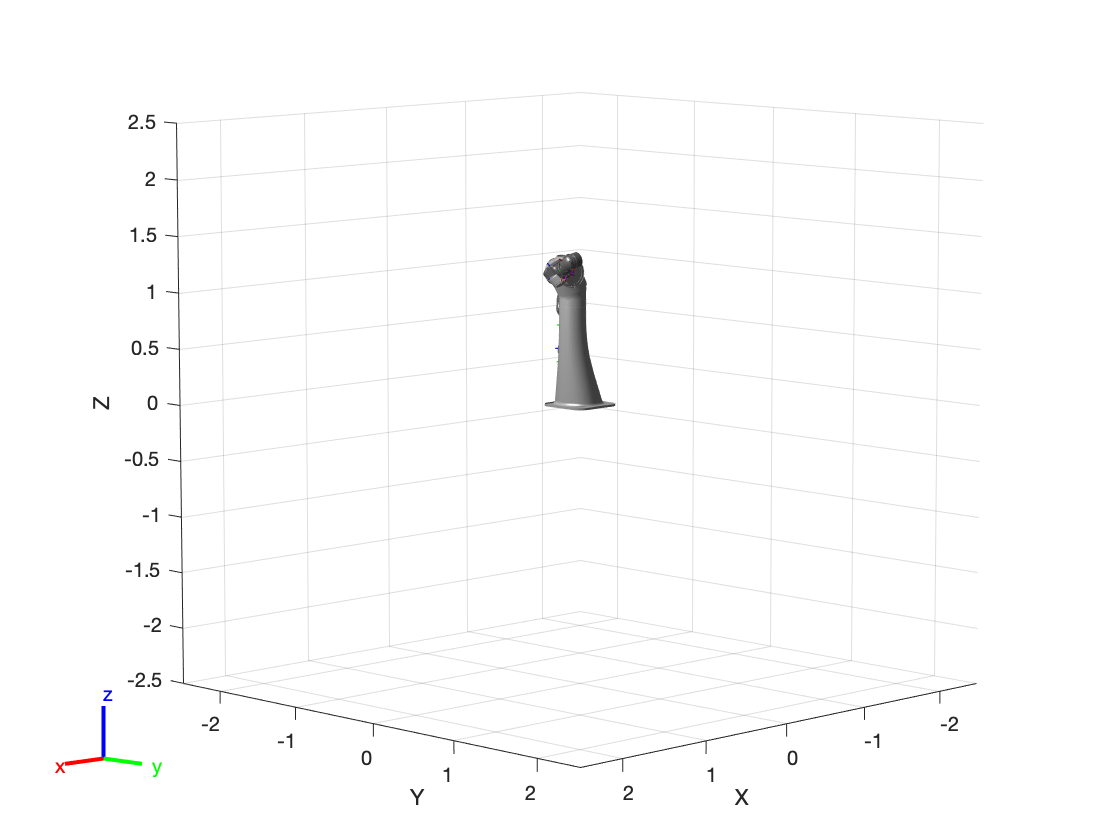

V = 6×1
   -0.1640
   -0.0795
   -0.4577
    0.4274
    0.0583
   -0.1951


theta = 1×8
   -6.7266    3.5171  -13.5467   64.0717   15.6051  -72.6584    1.1130  -32.0273


while norm(omega_b) > epsilon_w && norm(v_b) > epsilon_v && i < 50 %set max iterations
    i=i+1
    
%     F(i) = getframe(show(robot,[theta theta(2:8) 0])); %both arms
    F(i) = getframe(show(robot,[theta pi/2 pi/2 zeros(1,6)])); %one arm

%% jacobian and transform function from robotics toolbox (iterative with each new theta)
    full_robot_jacobian=geometricJacobian(robot,[theta pi/2 pi/2 zeros(1,6)],"arm_left_link_7_t");
    Jb=full_robot_jacobian(:,1:8);
    T_sb=getTransform(robot,[theta pi/2 pi/2 zeros(1,6)],"arm_left_link_7_t");


    %%finding J-dagger 
    J_pseudo=Jb.'*((Jb*Jb.')^-1);

    %finding V
    Vb_box=logm(T_sb^-1*T_sd); 

    omega_b=[Vb_box(3,2);Vb_box(1,3);Vb_box(2,1)];
    v_b=[Vb_box(1,4);Vb_box(2,4);Vb_box(3,4)];
    V=[omega_b;v_b]

    %calculating difference between current joint angles and
    %predicted joint angles (theta_delta) using least-square linear optimization 
    alpha = Js*theta_delta
    epsilon = Js*theta_delta
    p_goal=T_sd
    t=T_sb
    C=skewdec(alpha)*t+epsilon+t-p_goal; C*x=d
    
    x = lsqlin(C,d,A,b,Aeq,beq,lb,ub,x0,options)

    theta_delta = J_pseudo * V ;
    
    
    %adding that difference onto the previous theta
    theta=theta+theta_delta.'
end

fig = figure;
movie(fig,F,2)